clear;
close all;
clc;
initime = clock;
% cd 
addpath('../funcs');
load ../../data/all_0_0.5_0_0.05_Iattn_0.02.mat
load ../../data/tPET_0.22_0.42_0.034_0.034_Iattn_0.02.mat

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 4;
steps = size(orderSheet,1);

## Parameter plane

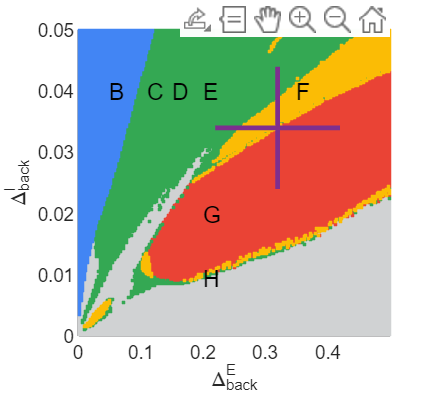

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

figure();

% INF
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) == -1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor",[209 211 212]/256); % grey
    hold on
end

% ROI: OSC-OSC: order and level agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#EA4335"); % red
    hold on
end

% OSC-OSC: order disagree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) ~= 1 && sum(osciSheet(i,j,1,:)==1)==5 && sum(osciSheet(i,j,2,:)==1)==5
            roi(i,j) = 1;
        end
    end
end

for i = 1:steps
    for j = 1:steps
        if level(i,j) ~= 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#34A853"); % green
    hold on
end

% STY-STY
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) ~= -1 && sum(osciSheet(i,j,2,:)==1)<5
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on
end


% gamma/+beta but order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if level(i,j) == 1 && orderSheet(i,j) == 1 && sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end
roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
    hold on
end

% % unstable oscillation: chaos?
% roi = zeros(steps,steps);
% for i = 1:steps
%     for j = 1:steps
%         if sum(osciSheet(i,j,2,:)==1)>0 && sum(psdSheet(i,j,2:6) > 10) > 0
%             roi(i,j) = 1;
%         end
%     end
% end
% roi = roi == 1;
% for i = 1:steps
%     x = Delta_e(roi(steps+1-i,:));
%     y = Delta_i(i)*ones(length(x),1);
%     s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ED5564"); % red
%     hold on
% end

% scatter(0.05, 0.04,"o","filled",'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',[0 0 0]);
textSize = 10;
text(0.05, 0.04, 'B', 'FontSize',textSize)
text(0.11, 0.04,'C', 'FontSize',textSize);
text(0.15, 0.04,'D', 'FontSize',textSize);
text(0.2, 0.04,'E', 'FontSize',textSize);
% text(0.26, 0.04,'F', 'FontSize',textSize);
text(0.35, 0.04,'F', 'FontSize',textSize);

text(0.2, 0.02,'G', 'FontSize',textSize);
text(0.2, 0.0095,'H', 'FontSize',textSize);

xlabel("\Delta_{back}^{E}");
ylabel("\Delta_{back}^{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
box on;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
% print('paraPlane', '-dpng', '-r600');
% print('paraPlane', '-depsc', '-r600');

% add experiment line (0.32, 0.034)
line([0.22, 0.42], [0.034, 0.034], 'Color', "#7E2F8E", 'LineWidth', 2);
line([0.32, 0.32], [0.024, 0.044], 'Color', "#7E2F8E", 'LineWidth', 2);

load ../../data/tPET_0.22_0.42_0.034_0.034_Iattn_0.02.mat

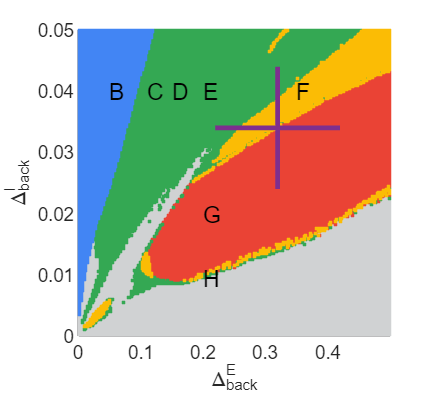

plot(squeeze(tPET(100,2,2,:,3)));